部分解答附于pdf中。

**5.1**

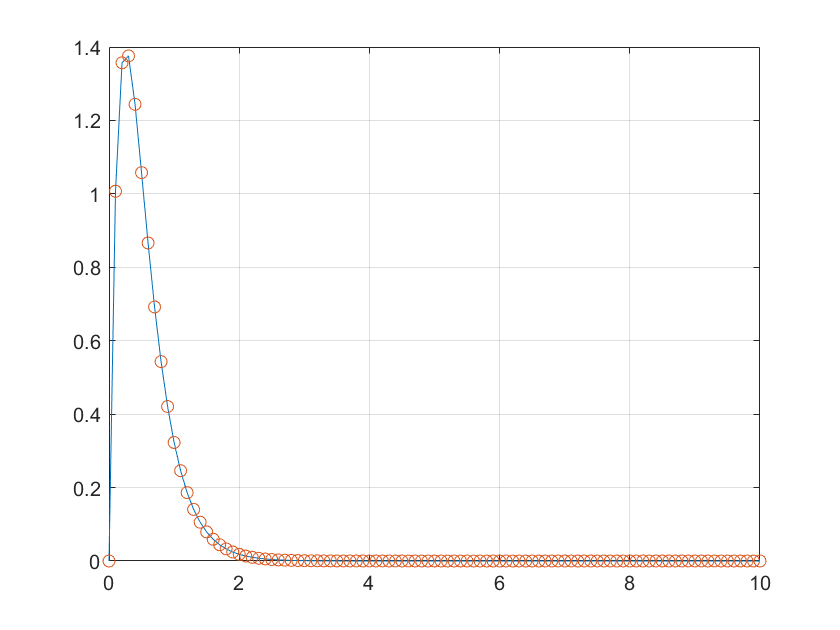

num=15;den=[1, 8, 15];
sys = tf(num, den);
t = 0:0.1:10;
y1 = impulse(sys, t);
y2 = 15/2 * (exp(-3*t)-exp(-5*t));
plot(t, y1, t, y2, 'o'),grid;

**5.2**

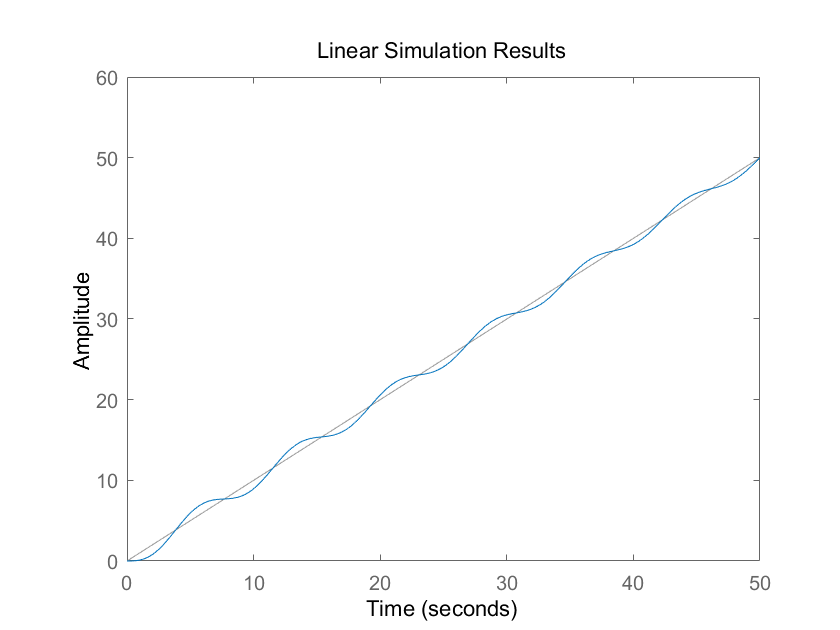

num = [1, 10]; den = [1, 15, 0, 0];
sys1 = tf(num, den);
sys = feedback(sys1, 1, -1);
t = 0:0.1:50;
lsim(sys, t, t)

**5.3**

figure;
t = 0:0.1:30;
i = 1

i = 1

for omega = [2 1]
    for zeta = [0 0.1 0.2]
        if [omega, zeta] == [2, 0.2]
            continue
        elseif [omega, zeta] == [1, 0.1]
            continue
        else
            sys = tf(omega*omega, [1, 2*zeta*omega, omega*omega]);
            y = impulse(sys, t);
            subplot(2, 2, i), plot(t, y)
            i = i + 1;
        end
    end
end

**5.4**

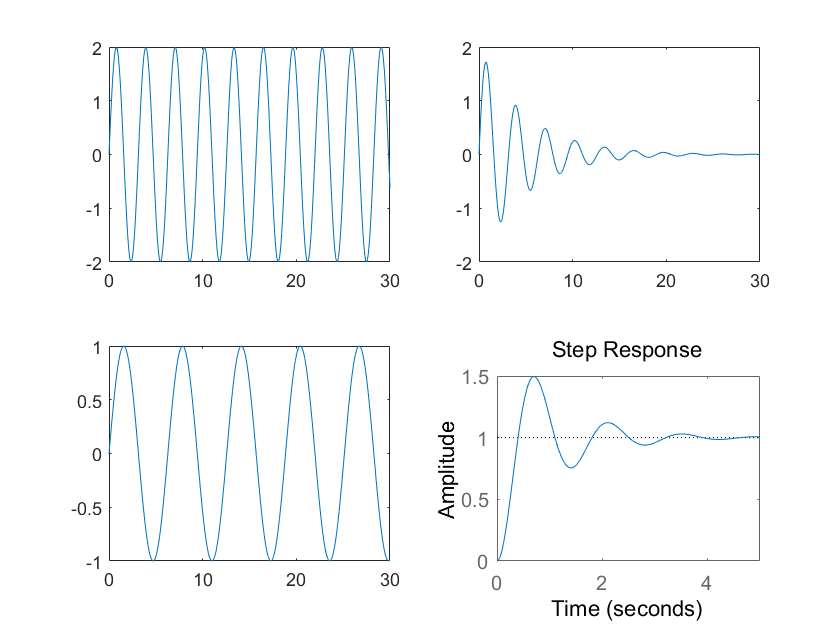

%(b)
num=21;den=[1, 2, 0];
sys1 = tf(num, den);
sys = feedback(sys1, 1, -1);
t = 0:0.01:5;
step(sys, t)

**5.5**

num = 25; den = [1, 5, 0];
sys1 = tf(num, den);
sys = feedback(sys1, 1, -1);
t = 0:0.001:4;
y = step(sys, t);
plot(t, y), grid


idx = find(y==max(y));
Tp = t(idx) 

Tp = 0.7260

Mpt  = (y(idx)-1)/1

Mpt = 0.1630

text(Tp, y(idx), 'o', 'color', 'r')
text(Tp, y(idx), ['   ', num2str(Tp), ',', num2str(y(idx))], 'color', 'r')

%idx = find(abs(y-1)/1 <= 0.02, 1, 'first')
Ts = 1.62;
idx = find(abs(t-Ts)<1e-3, 1)

idx = 1621

Ts = t(idx)

Ts = 1.6200

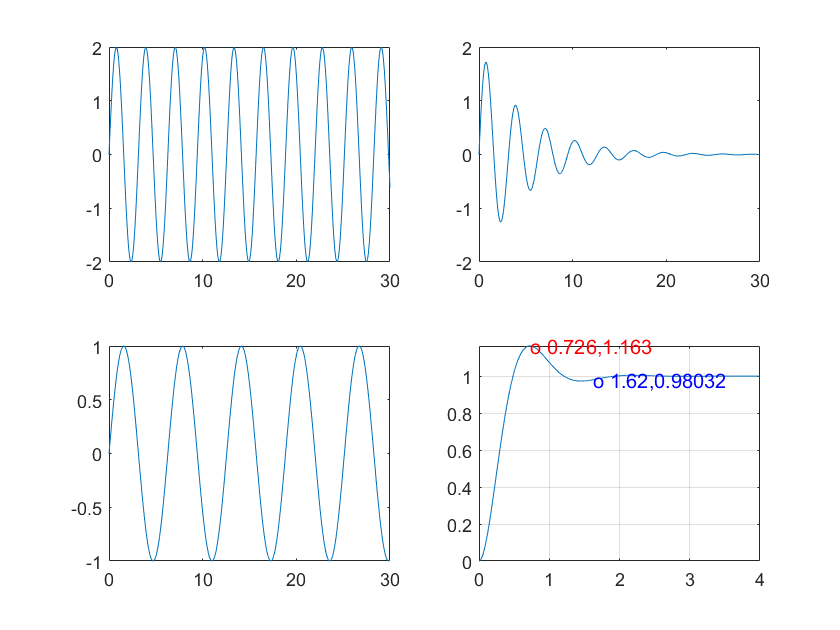

text(Ts, y(idx), 'o', 'color', 'b')
text(Ts, y(idx), ['   ', num2str(Ts), ',', num2str(y(idx))], 'color', 'b')

**5.6**

(a)

sys1 = tf([0.5, 2], [1,0]);
sys2 = tf([1], [1, 2, 0]);
sys3 = series(sys1, sys2);
sys = feedback(sys3, 1, -1)

sys =
 
         0.5 s + 2
  -----------------------
  s^3 + 2 s^2 + 0.5 s + 2
 
Continuous-time transfer function.



(b)

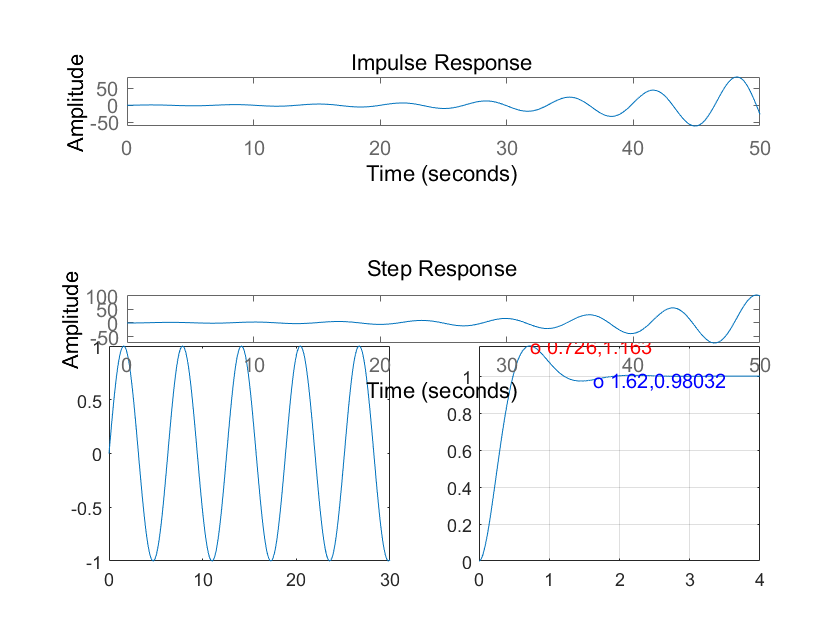

t = [0:0.1:50];
subplot(511), impulse(sys, t)
subplot(513), step(sys, t)

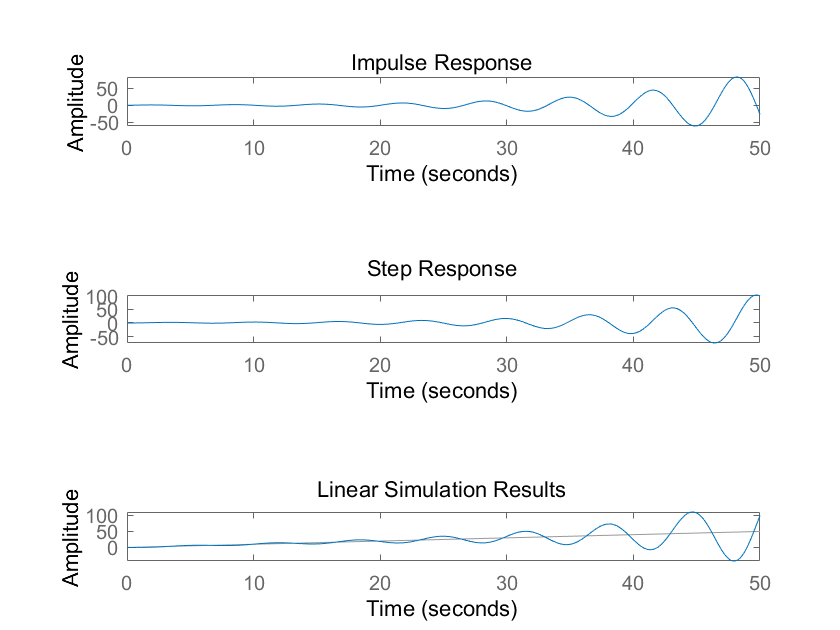

subplot(515), lsim(sys, t, t)